# projet muttin de team baptiste

版本1，正常模板

## paramètre

f=@(x,y) -15*(x^2+y^2)

f = function_handle with value:
    @(x,y)-15*(x^2+y^2)


Tcontour=28;
h=1/3;
longueur=3; %longueur de la pièce = son largeur

## matrice coef A

A1=diag(-4*ones(2,1))+diag(ones(1,1),-1)+diag(ones(1,1),1)

A1 =     -4     1
     1    -4


A2=diag(ones(1,2))

A2 =      1     0
     0     1


A=[A1 A2; 
   A2 A1]

A =     -4     1     1     0
     1    -4     0     1
     1     0    -4     1
     0     1     1    -4


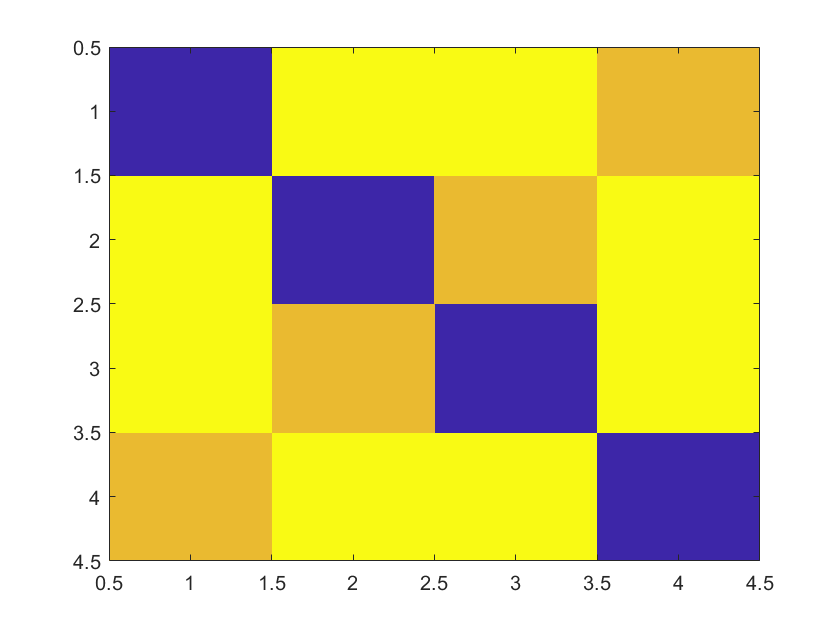

imagesc(A)

## vecteur cste C

temp=zeros(longueur-1); %temporary
for i=1:2 % ligne
    for j=1:2 % colonne
        temp(i,j)=h^2*f(i,j)-2*Tcontour;
    end
end
temp

temp =   -59.3333  -64.3333
  -64.3333  -69.3333


C=zeros(length(temp)^2,1);
for i=1:length(temp)
    C(1+(i-1)*2 : 2+(i-1)*2  , 1)=temp(i,:);
end
C

C =   -59.3333
  -64.3333
  -64.3333
  -69.3333


## vecteur Tvec

Tvec=A\C

Tvec =    30.9167
   32.1667
   32.1667
   33.4167


## matrice final Z

Z=zeros(length(temp)+2)

Z =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


for i=2:length(Z)-1
    Z(i, 2:length(Z)-1)=Tvec(1+2*(i-2):2+2*(i-2));
end

Z(1,:)=Tcontour;
Z(length(Z),:)=Tcontour;
Z(:,1)=Tcontour;
Z(:,length(Z))=Tcontour;
Z

Z =    28.0000   28.0000   28.0000   28.0000
   28.0000   30.9167   32.1667   28.0000
   28.0000   32.1667   33.4167   28.0000
   28.0000   28.0000   28.0000   28.0000


## visualisation

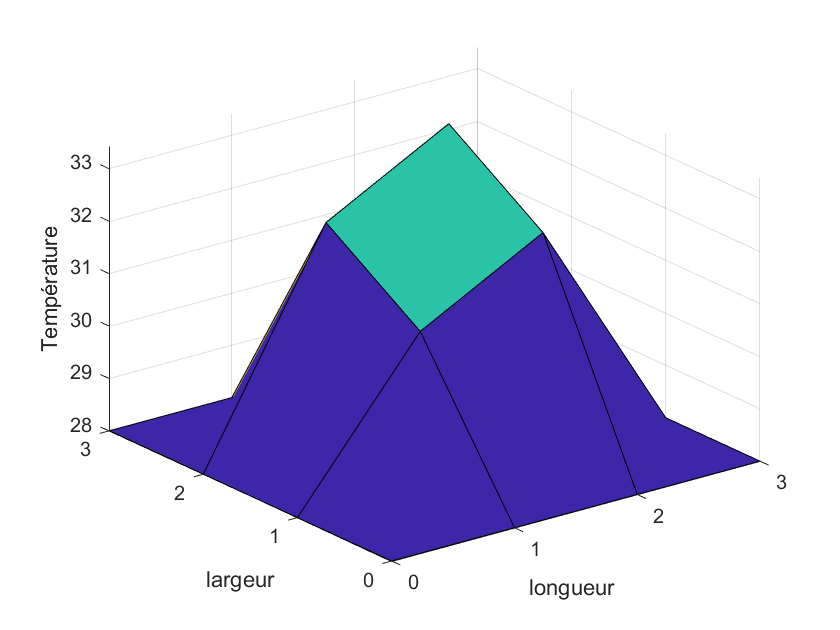


figure(1)
[xq,yq] = meshgrid(0:longueur, 0:longueur);
surfc(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

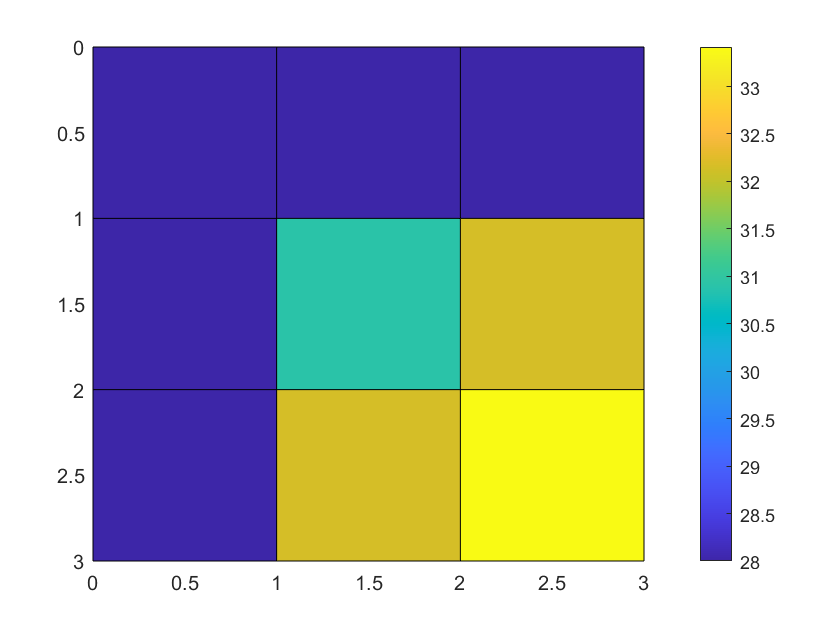


figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar

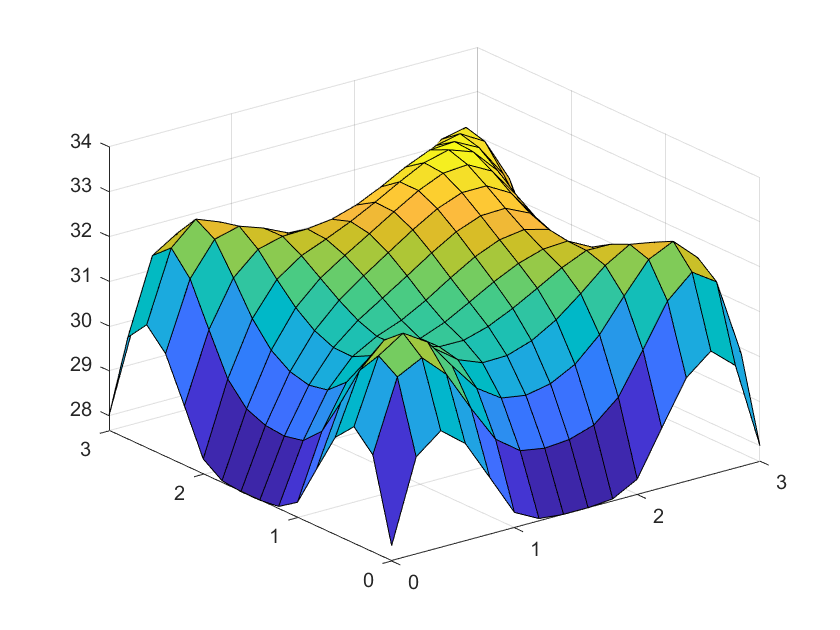


figure(3)
% nbr_pts=5 % nbr de pts entre deux pts originaux
% accuracy=1/nbr_pts;
[xqq,yqq] = meshgrid(0:accuracy:longueur, 0:accuracy:longueur); %précision d'interpolation
vq = griddata(xq,yq,Z,xqq,yqq,'v4');
surf(xqq,yqq,vq)